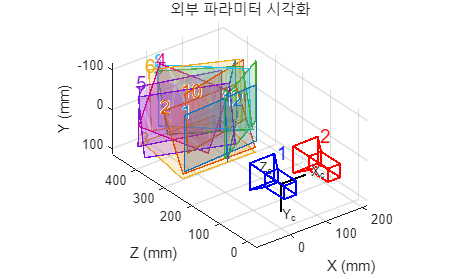

% Load the stereoParameters object.
load("handshakeStereoParams.mat");

% Visualize camera extrinsics.
showExtrinsics(stereoParams);

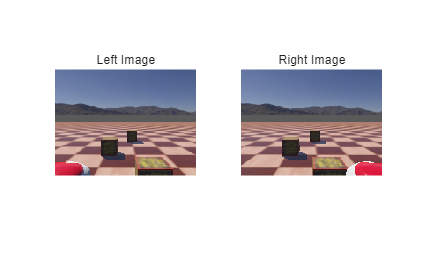

% 2. 좌우 이미지 불러오기
frameLeft = imread('resource/img/top_l/frame_1.png');
frameRight = imread('resource/img/top_r/frame_1.png');

figure;
subplot(1,2,1);
imshow(frameLeft);
title('Left Image');

subplot(1,2,2);
imshow(frameRight);
title('Right Image');

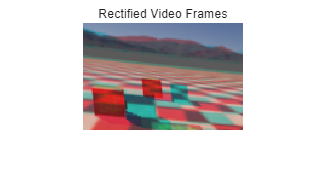

% 3. 스테레오 보정 (Rectification)
[frameLeftRect, frameRightRect, reprojectionMatrix] = ...
    rectifyStereoImages(frameLeft, frameRight, stereoParams);

% 4. 흑백 변환
frameLeftGray  = im2gray(frameLeftRect);
frameRightGray = im2gray(frameRightRect);

figure;
imshow(stereoAnaglyph(frameLeftRect, frameRightRect));
title("Rectified Video Frames");

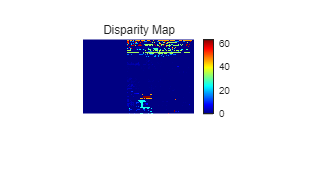


% 5. Disparity Map 계산
disparityMap = disparitySGM(frameLeftGray, frameRightGray, ...
    'DisparityRange', [0 64], 'UniquenessThreshold', 15);

% 6. Depth (3D Scene) 재구성
points3D = reconstructScene(disparityMap, reprojectionMatrix);
points3D = points3D ./ 1000;  % mm → m

% 7. 시각화
figure;
imshow(disparityMap, [0, 64]);
title('Disparity Map');
colormap jet; colorbar;

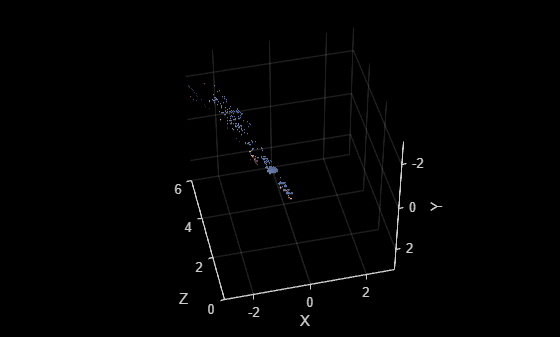


% 8. 3D 포인트 클라우드 표시
ptCloud = pointCloud(points3D, 'Color', frameLeftRect);
player3D = pcplayer([-3, 3], [-3, 3], [0, 6], ...
    'VerticalAxis','y','VerticalAxisDir','down');
view(player3D, ptCloud);

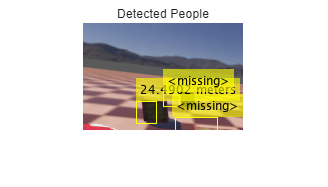

if ~exist("yoloDet","var") || isempty(yoloDet)
    yoloFile = "detector_nao.mat";   % 필요 시 절대·상대 경로 조정
    fprintf("Loading YOLO detector from %s ...\n", yoloFile);
    tmp      = load(yoloFile,"detector");   % 'detector' 변수만 로드
    yoloDet  = tmp.detector;                % yolov4ObjectDetector
    fprintf("YOLO detector loaded ✔︎\n\n");
end

rgb=frameLeft;

[bboxes,scores,labels] = detect(yoloDet,rgb,Threshold=0.25);
        annStr = string(labels)+" : "+string(round(scores,2));
        rgbDisp = insertObjectAnnotation(rgb,"rectangle",bboxes,annStr);

% Find the centroids of detected people.
centroids = [round(bboxes(:, 1) + bboxes(:, 3) / 2), ...
    round(bboxes(:, 2) + bboxes(:, 4) / 2)];

% Find the 3-D world coordinates of the centroids.
centroidsIdx = sub2ind(size(disparityMap), centroids(:, 2), centroids(:, 1));
X = points3D(:, :, 1);
Y = points3D(:, :, 2);
Z = points3D(:, :, 3);
centroids3D = [X(centroidsIdx)'; Y(centroidsIdx)'; Z(centroidsIdx)'];

% Find the distances from the camera in meters.
dists = sqrt(sum(centroids3D .^ 2));
    
% Display the detected people and their distances.
labels = dists+" meters";
figure
imshow(insertObjectAnnotation(frameLeftRect, "rectangle", bboxes, labels));
title("Detected People");

% % ─────────────────────────────────────────────────────
% % 폴더 설정
% folderL = 'resource/img/top_l/';
% folderR = 'resource/img/top_r/';
% 
% % 영상 저장 경로
% outputVideoL = 'top_l_video.avi';
% outputVideoR = 'top_r_video.avi';
% 
% % 이미지 파일 목록 읽기
% imgFilesL = dir(fullfile(folderL, 'frame_*.png'));
% imgFilesR = dir(fullfile(folderR, 'frame_*.png'));
% 
% % 프레임 정렬 (frame_1.png, frame_2.png, ...)
% imgFilesL = sort({imgFilesL.name});
% imgFilesR = sort({imgFilesR.name});
% 
% % 첫 프레임으로 영상 정보 얻기
% firstImgL = imread(fullfile(folderL, imgFilesL{1}));
% [H, W, ~] = size(firstImgL);
% fps = 10;  % 원하면 수정 가능
% 
% % 비디오 객체 생성
% writerL = VideoWriter(outputVideoL, 'Motion JPEG AVI');
% writerR = VideoWriter(outputVideoR, 'Motion JPEG AVI');
% writerL.FrameRate = fps;
% writerR.FrameRate = fps;
% 
% open(writerL);
% open(writerR);
% 
% % 영상 프레임 작성
% for i = 1:min(length(imgFilesL), length(imgFilesR))
%     imgL = imread(fullfile(folderL, imgFilesL{i}));
%     imgR = imread(fullfile(folderR, imgFilesR{i}));
% 
%     writeVideo(writerL, imgL);
%     writeVideo(writerR, imgR);
% end
% 
% close(writerL);
% close(writerR);
% 
% fprintf("✅ 영상 생성 완료:\n  %s\n  %s\n", outputVideoL, outputVideoR);

✅ 영상 생성 완료:
  top_l_video.avi
  top_r_video.avi


vslam = stereovslam(intrinsics, baseline, ...
    MaxNumPoints=1000, SkipMaxFrames=5, DisparityRange=[0, 64]);

'intrinsics'은(는) 인식할 수 없는 함수 또는 변수입니다.


for i = 1:numel(imdsLeft.Files)
    ILeft  = readimage(imdsLeft, i);
    IRight = readimage(imdsRight, i);
    addFrame(vslam, ILeft, IRight);

    if hasNewKeyFrame(vslam)
        plot(vslam); % 3D map + camera trajectory
    end

    if checkStatus(vslam) == uint8(0)
        break;
    end
end
